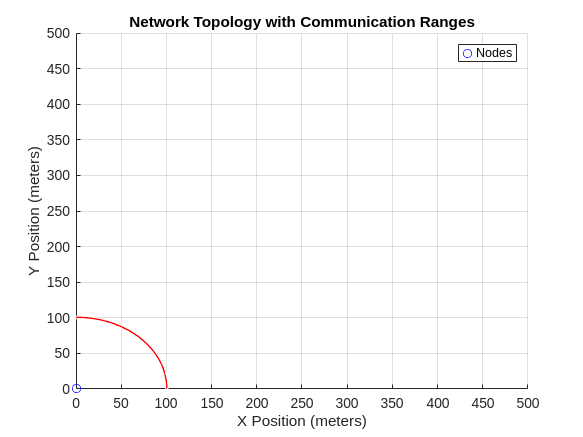

% Parameters
numNodes = 10; % Number of nodes
networkRange = 100; % Communication range in meters
nodePositions = rand(numNodes, 2) * 500; % Random node positions in a 500x500 area
nodeEnergy = ones(numNodes, 1) * 1000; % Initial energy of each node
fs = 1e6; % Sampling frequency for waveform generation
symbolRate = 1e3; % Symbol rate (1k symbols per second)
modulationOrder = 2; % BPSK (2 symbols)
messageLength = 100; % Length of message (in symbols)

% Step 1: Define PHY layer parameters
pathLossExponent = 2; % Path loss exponent
noiseLevel = 0.1; % Noise level

% Step 2: Create a figure for visualizations (network topology)
figure;
hold on;
axis([0 500 0 500]);
xlabel('X Position (meters)');
ylabel('Y Position (meters)');
grid on;
title('Network Topology with Communication Ranges');
% Plot node positions and communication ranges
plot(nodePositions(:,1), nodePositions(:,2), 'bo'); % All nodes in blue
for i = 1:numNodes
    viscircles(nodePositions(i,:), networkRange, 'Color', 'r', 'LineWidth', 1); % Communication range in red
end
hold off;
% Step 3: Simulate data transmission with waveforms
transmitData = @(sender, receiver) simulateTransmission(sender, receiver, nodePositions, fs, symbolRate, messageLength, pathLossExponent, networkRange, noiseLevel);

% Step 4: Network Layer - Flooding
receivedPackets = zeros(numNodes, numNodes); % Matrix to store which nodes receive packets

% Simulate flooding from each node

hold off;

% Display the network topology visualization
legend('Nodes', 'Communication Range', 'Successful Transmission', 'Failed Transmission');


% Step 5: Calculate performance metrics (e.g., packet delivery ratio)
packetDeliveryRatio = sum(receivedPackets(:)) / (numNodes * (numNodes - 1));
disp(['Packet Delivery Ratio: ', num2str(packetDeliveryRatio)]);

Packet Delivery Ratio: 0



% Transmission Simulation Function
function success = simulateTransmission(sender, receiver, nodePositions, fs, symbolRate, messageLength, pathLossExponent, range, noise)
    % Generate the baseband BPSK signal for the sender
    message = randi([0 1], messageLength, 1); % Random binary message
    transmittedSignal = generateBPSKSignal(message, fs, symbolRate);
    
    % Clear the figure and plot the transmitted BPSK waveform for each new transmission
    figure('Name', 'Transmitted BPSK Signal'); 
    clf; % Clear the previous figure
    subplot(2,1,1);
    t = (0:length(transmittedSignal)-1) / fs;
    plot(t, transmittedSignal);
    title('Transmitted BPSK Signal');
    xlabel('Time (s)');
    ylabel('Amplitude');
    
    % Calculate the distance between the sender and receiver
    distance = norm(nodePositions(sender, :) - nodePositions(receiver, :));
    
    if distance < range
        % Apply simple path loss model
        pathLoss = 1 / (distance^pathLossExponent);
        signalToNoiseRatio = pathLoss / noise;
        
        % Apply noise to the transmitted signal (to simulate channel noise)
        receivedSignal = transmittedSignal * sqrt(pathLoss) + noise * randn(size(transmittedSignal));
        
        % Plot received signal
        subplot(2,1,2);
        plot(t, receivedSignal);
        title('Received Signal with Noise and Path Loss');
        xlabel('Time (s)');
        ylabel('Amplitude');
        
        % Demodulate the received signal at the receiver
        receivedMessage = demodulateBPSK(receivedSignal, fs, symbolRate);
        
        % Check if the received message matches the transmitted message
        success = isequal(message, receivedMessage);
    else
        success = false;
    end
end

% BPSK Signal Generation Function
function signal = generateBPSKSignal(message, fs, symbolRate)
    % Time vector based on symbol rate and message length
    t = 0:1/fs:(length(message)/symbolRate - 1/fs);
    
    % Map binary message to BPSK symbols (0 -> -1, 1 -> 1)
    bpskSymbols = 2*message - 1;
    
    % Generate the BPSK modulated signal
    signal = [];
    for i = 1:length(message)
        % Repeat each symbol over one symbol period
        signal = [signal, bpskSymbols(i) * cos(2*pi*symbolRate*t(1:round(length(t)/length(message))))];
    end
end

% BPSK Demodulation Function
function decodedMessage = demodulateBPSK(signal, fs, symbolRate)
    % Time vector
    t = 0:1/fs:(length(signal)/fs - 1/fs);
    
    % Matched filtering (for simplicity, we use a correlation with the carrier)
    carrier = cos(2*pi*symbolRate*t);
    demodulatedSignal = signal .* carrier;
    
    % Integrate over symbol periods and decide on the bit (1 if positive, 0 if negative)
    symbolDuration = round(length(signal)/length(t));
    symbols = reshape(demodulatedSignal, symbolDuration, []);
    symbolEnergy = sum(symbols, 1);
    
    % Map the energy to binary values (0 or 1)
    decodedMessage = symbolEnergy > 0;
end